### Circuito Linea de Tranmision

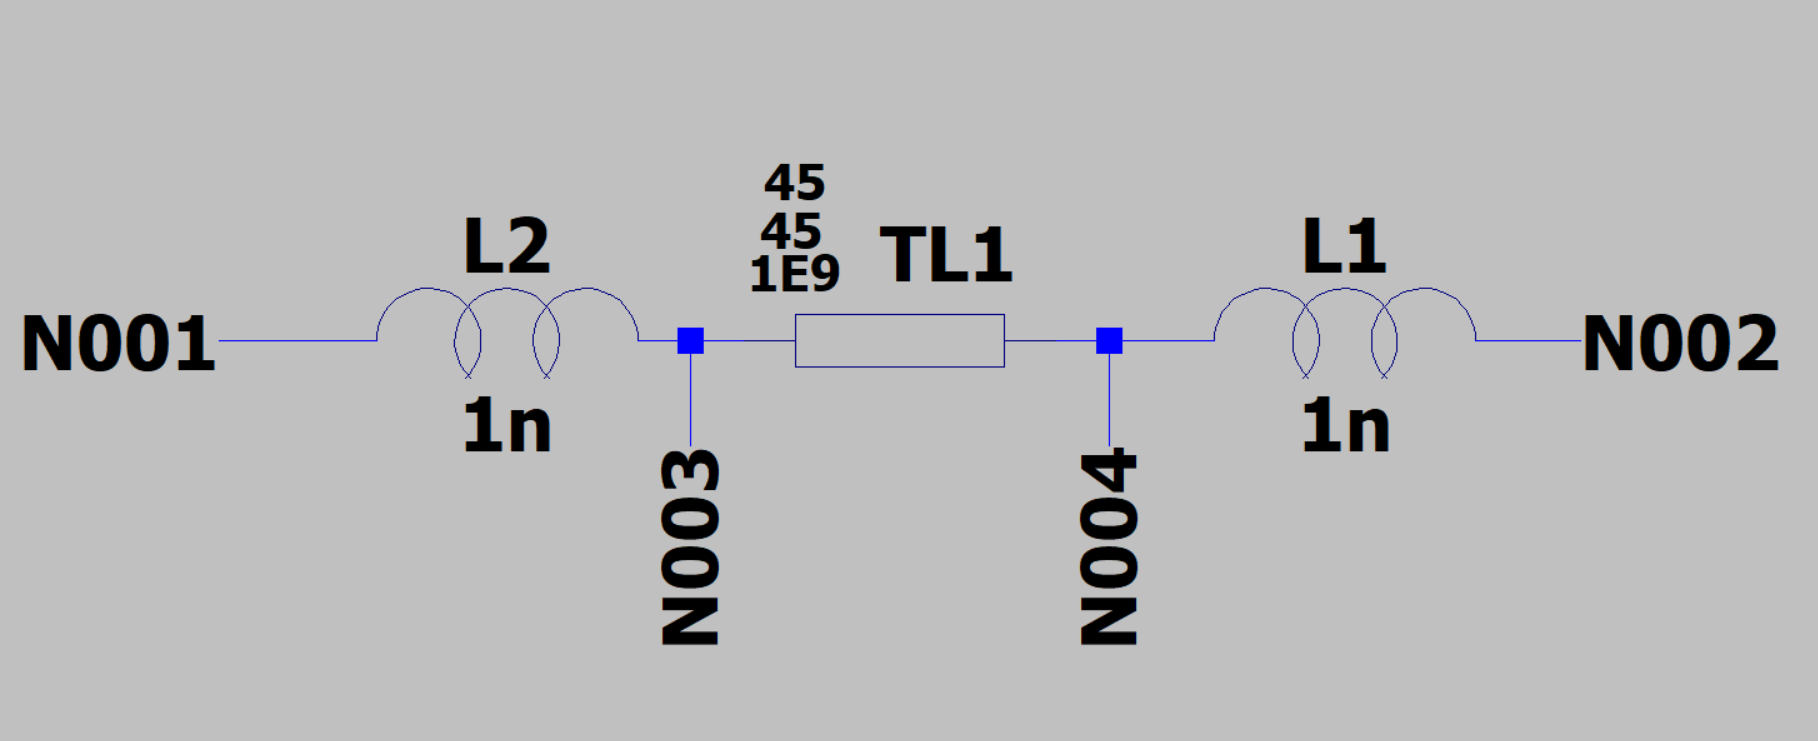

clear all
Frec_inicial=0.1E9;
Frec_final=2E9;
Muestreo=1000;
Z0=50;

netlist_TLfile='NetlistSpice\LineaTransmision.net';
netlistCell=Netlist2CellArray(netlist_TLfile)

netlistCell = 3×7 cell array
    {'L1' }    {'N004'}    {'N002'}    {'L' }    {[1.0000e-09]}    {[ 0]}    {[         0]}
    {'TL1'}    {'N003'}    {'N004'}    {'TL'}    {[        45]}    {[45]}    {[1.0000e+09]}
    {'L2' }    {'N001'}    {'N003'}    {'L' }    {[1.0000e-09]}    {[ 0]}    {[         0]}



SMatlab4=SParametersFromNetlist(netlistCell,Frec_inicial,Frec_final,Muestreo,Z0);

TL =   txlineElectricalLength: ElectricalLength element

                  Name: 'ElectricalLength'
                    Z0: 45
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'NotApplicable'
              StubMode: 'NotAStub'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


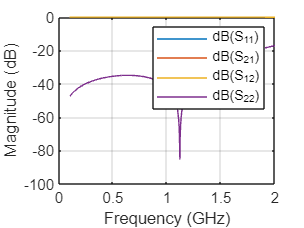

rfplot(SMatlab4);

pat=digitsPattern;
nuevo_Netlist=NetlistCircuitoEquivalente(netlistCell)

nodoInicial = "N004"

nodoFinal = "N002"

nodoInicial = "N003"

nodoFinal = "N004"

nodoInicial = "N001"

nodoFinal = "N003"

nuevo_Netlist = 5×7 cell array
    {'L1'   }    {'N004'  }    {'N002'  }    {'L'    }    {[1.0000e-09]}    {[     0]}    {[         0]}
    {'L2'   }    {'N001'  }    {'N003'  }    {'L'    }    {[1.0000e-09]}    {[     0]}    {[         0]}
    {'TL_Y1'}    {["N003"]}    {["N004"]}    {'TL_Y1'}    {[        45]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y2'}    {["N003"]}    {[     0]}    {'TL_Y2'}    {[        45]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y3'}    {["N004"]}    {[     0]}    {'TL_Y3'}    {[        45]}    {[0.7854]}    {[1.0000e+09]}



% ----- INICIO----------

function netlistCell= NetlistCircuitoEquivalente(netlistCell)
    
    % Convertir char a string, es mas facil comparar
    nodoInicial_Col=convertCharsToStrings(netlistCell(:,2));
    nodoFinal_Col=convertCharsToStrings(netlistCell(:,3));

    % Inicialización de variable para guardar info
    X=1;

    % Se recorre el netlist para encontrar distribuidos
    for i=1:size(netlistCell,1)
            
            nodoInicial=nodoInicial_Col(i)
            nodoFinal=nodoFinal_Col(i)
            type=cell2mat(netlistCell(i,4));
            value=cell2mat(netlistCell(i,5));
            Bl= cell2mat(netlistCell(i,6));
            Bl=deg2rad(Bl);
            opFreq=cell2mat(netlistCell(i,7));
    
            if type=='TL'
                % Guarda informacion de los distribuidos
                Info(X,:)={nodoInicial,nodoFinal,value,Bl,opFreq};
                Posicion=i;
                X=X+1;
            end
    
    end
    
    % Con la información obtenida, crea el nuevo netlist
    for j=1:size(Info,1)
        
        %Eliminar componente distribuido
        netlistCell(Posicion,:)=[];
    
        % Agregar circuito equivalente
        % Y1=Y12, Y2=Y11-Y12 y Y3=Y22-Y12
        last_column=size(netlistCell,1)+1;
        Y1=[{'TL_Y1'},{Info{j,1}},{Info{j,2}},{'TL_Y1'},{Info{j,3}},{Info{j,4}},{Info{j,5}}];
        Y2=[{'TL_Y2'},{Info{j,1}},{0},{'TL_Y2'},{Info{j,3}},{Info{j,4}},{Info{j,5}}];
        Y3=[{'TL_Y3'},{Info{j,2}},{0},{'TL_Y3'},{Info{j,3}},{Info{j,4}},{Info{j,5}}];
        netlistCell(last_column:last_column+2,:)=[Y1;Y2;Y3];
    
    end

end
